# Task 3: The spin-1/2 Heisenberg dimer

The problem of two spin-1/2 particles interacting with each other with the so-called Heisenberg exchange coupling is described by the Hamiltonian 


$$\mathcal{H} = J {\bf S}_1 \cdot {\bf S}_2=J (S_{1x}S_{2x}+S_{1y}S_{2y}+S_{1z}S_{2z})\,,$$


where $J$ is a real number.

# Subtask a

Write a few lines of code that deliver the matrix representations of the operators 


$$S_{1x}, S_{1y}, S_{1z}, S_{2x}, S_{2y}, S_{2z}, S_x\equiv S_{1x}+S_{2x},
S_y\equiv S_{1y}+S_{2y},
S_z\equiv S_{1z}+S_{2z}, 
{\bf S}^2 \equiv S_x^2+S_y^2+S_z^2$$


 in the `product-$S_z$ basis'.

[Sx, Sy, Sz]=FetchSpinMatrices(0.5);
S1x = kron(Sx,eye(2))

S1x =          0         0    0.5000         0
         0         0         0    0.5000
    0.5000         0         0         0
         0    0.5000         0         0


S2x = kron(eye(2),Sx)

S2x =          0    0.5000         0         0
    0.5000         0         0         0
         0         0         0    0.5000
         0         0    0.5000         0


S1y = kron(Sy,eye(2))

S1y =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i


S2y = kron(eye(2),Sy)

S2y =    0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.0000i


S1z = kron(Sz,eye(2))

S1z =     0.5000         0         0         0
         0    0.5000         0         0
         0         0   -0.5000         0
         0         0         0   -0.5000


S2z = kron(eye(2),Sz)

S2z =     0.5000         0         0         0
         0   -0.5000         0         0
         0         0    0.5000         0
         0         0         0   -0.5000


Sx = S1x + S2x

Sx =          0    0.5000    0.5000         0
    0.5000         0         0    0.5000
    0.5000         0         0    0.5000
         0    0.5000    0.5000         0


Sy = S1y + S2y

Sy =    0.0000 + 0.0000i   0.0000 - 0.5000i   0.0000 - 0.5000i   0.0000 + 0.0000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.5000i
   0.0000 + 0.0000i   0.0000 + 0.5000i   0.0000 + 0.5000i   0.0000 + 0.0000i


Sz = S1z + S2z

Sz =      1     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0    -1


Ssquared = Sx^2 + Sy^2 + Sz^2

Ssquared =      2     0     0     0
     0     1     1     0
     0     1     1     0
     0     0     0     2


# Subtask b

Write a few lines of code that deliver the matrix representation of $\mathcal{H}$ for $J=1$. Solve the Schroedinger equation (eigenvalue matrix equation) to obtain the energy eigenvalues and the corresponding eigenstates of $\mathcal{H}$. 

J = 1

J = 1

Hamiltonian = J*(S1x*S2x + S1y*S2y +S1z*S2z)

Hamiltonian =     0.2500         0         0         0
         0   -0.2500    0.5000         0
         0    0.5000   -0.2500         0
         0         0         0    0.2500


[V,D] = eig(Hamiltonian)

V =          0    1.0000         0         0
    0.7071         0    0.7071         0
   -0.7071         0    0.7071         0
         0         0         0    1.0000


D =    -0.7500         0         0         0
         0    0.2500         0         0
         0         0    0.2500         0
         0         0         0    0.2500


Energy = eig(Hamiltonian);
EigState1 = V(:,1)

EigState1 =          0
    0.7071
   -0.7071
         0


Energy1 = Energy(1)

Energy1 = -0.7500

EigState2 = V(:,2)

EigState2 =      1
     0
     0
     0


Energy2 = Energy(2)

Energy2 = 0.2500

EigState3 = V(:,3)

EigState3 =          0
    0.7071
    0.7071
         0


Energy3 = Energy(3)

Energy3 = 0.2500

EigState4 = V(:,4)

EigState4 =      0
     0
     0
     1


Energy4 = Energy(4)

Energy4 = 0.2500

# Subtask c

Calculate the commutator $[\mathcal{H},{\bf S}^2]$ and then check explicitly that each eigenstate of $\mathcal{H}$ is also an eigenstate of the operator ${\bf S}^2$. The corresponding eigenvalues are given by $S(S+1)$, where $S$ is the 'total spin quantum number'. What is value of $S$ for each eigenstate of $\mathcal{H}$?

HamiltonianCommutatorSsquared = Hamiltonian * Ssquared - Ssquared * Hamiltonian

HamiltonianCommutatorSsquared =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Ssquared*EigState1 ./EigState1

ans =    NaN
     0
     0
   NaN


Ssquared*EigState2 ./ EigState2

ans =      2
   NaN
   NaN
   NaN


Ssquared*EigState3 ./ EigState3

ans =    NaN
     2
     2
   NaN


Ssquared*EigState4 ./ EigState4

ans =    NaN
   NaN
   NaN
     2


%eigenvalues = 0,2,2,2
%total spin quantum number = 0,1,1,1 (or 0,-2,-2,-2)



# Subtask d

Plot the energy spectrum vs $J$, in the range $J \in [-3,3]$.

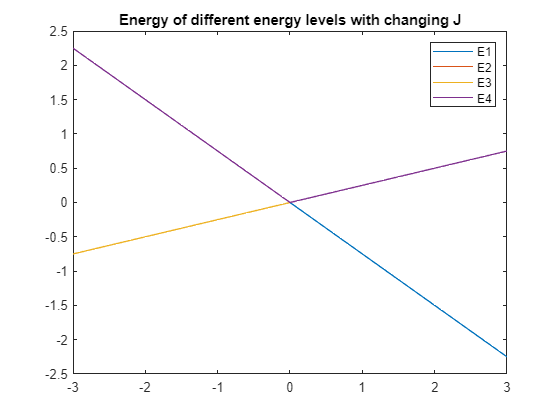

%add your code here
E1 = [];
E2 = [];
E3 = [];
E4 = [];

for J = -3:0.1:3;
    Hamiltonian = J*(S1x*S2x + S1y*S2y +S1z*S2z);
    Energy = eig(Hamiltonian);
    E1 = [E1 Energy(1)];
    E2 = [E2 Energy(2)];
    E3 = [E3 Energy(3)];
    E4 = [E4 Energy(4)];
end;
y = -3:0.1:3;
plot(y,E1)
hold on
plot(y,E2)
hold on
plot(y,E3)
hold on
plot(y,E4)
hold on
legend('E1','E2','E3','E4')
title("Energy of different energy levels with changing J")
hold off

# Subtask e

Plot the $\textbf{ground state}$ expectation value of the operator ${\bf S}^2$ vs $J$, in the range $J \in [-3,3]$.

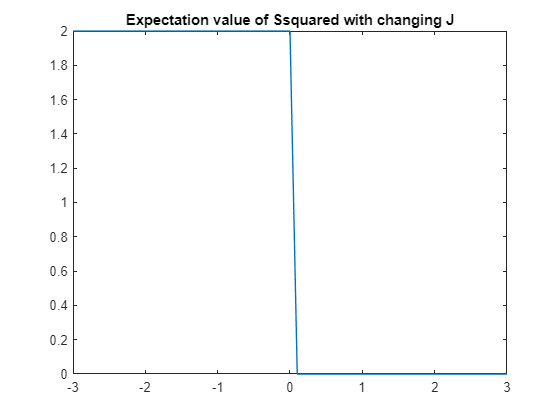

%add your code here
ExpectationSsquared = [];
for J = -3:0.1:3;
    Hamiltonian = J*(S1x*S2x + S1y*S2y +S1z*S2z);
    [V,D] = eig(Hamiltonian);
    EigState1 = V(:,1);
    E1ExpectationSsquared = EigState1' * Ssquared * EigState1;
    ExpectationSsquared = [ExpectationSsquared E1ExpectationSsquared];
end
ExpectationSsquared;
x = -3:0.1:3;
plot(x,ExpectationSsquared)
title("Expectation value of Ssquared with changing J")

Function for finding spin matracies as provided

function [Sx, Sy, Sz, Sp, Sm]=FetchSpinMatrices(S)

%sanity check
if rem(2*S,1)~=0; 
 disp('please provide an integer or half-integer value for S'); 
 return; 
end

dim=2*S+1; %dimension of Hilbert space

%initialize the matrices
Sx=zeros(dim,dim); Sy=zeros(dim,dim); Sz=zeros(dim,dim); Sp=zeros(dim,dim); Sm=zeros(dim,dim);


j=0;
for m=S:-1:-S; j=j+1;

 %Sz matrix
 Sz(j,j)=m;

 %Sp matrix
 f1=sqrt(S*(S+1)-m*(m+1));
 if f1~=0; 
  Sp(j-1,j)=f1; %matrix element between the bra <m+1| (corresponding to index j-1) and ket |m> (corresponding to index j)
 end

 %Sm matrix
 f2=sqrt(S*(S+1)-m*(m-1));
 if f2~=0; 
  Sm(j+1,j)=f2; %matrix element between the bra <m-1| (corresponding to index j+1) and ket |m> (corresponding to index j)
 end

end
Sx=(Sp+Sm)/2;
Sy=(Sp-Sm)/(2*complex(0,1));

return
end
